%loading the Data (Names denotes stations)
BUOY_44009 = readtable('buoy 44009 Nov all 2022.csv', VariableNamingRule='preserve');
WAVEGLIDER = readtable('WG Lewes.csv', VariableNamingRule='preserve');
DEOS_Reho_Station = readtable('DRHB.csv', VariableNamingRule='preserve');
Lewes_Station = readtable('LWSD1.csv', VariableNamingRule='preserve');
CapeMay_Station = readtable('cman4.csv', VariableNamingRule='preserve');
DEOS_India_Station = readtable('DIRL.csv', VariableNamingRule='preserve');


%DECARING THE VARIABLES COLUMNS FOR EACH STATION
%WaveGlider data
wgwspd = WAVEGLIDER{:,7}; wgTemp = WAVEGLIDER{:,5}; wgpres = WAVEGLIDER{:,6}; 
wgwdir = WAVEGLIDER{:,9}; wgwgust = WAVEGLIDER{:,13};

% %DECARING THE VARIABLES COLUMNS FOR EACH STATION
% %WaveGlider data
% wgwspdsk = WAVEGLIDER{:,7}; wgTemp = WAVEGLIDER{:,5}; wgpres = WAVEGLIDER{:,6}; 
% wgwdir = WAVEGLIDER{:,9}; wgwgust = WAVEGLIDER{:,13};

%Capemay data (NDBC)
CapeMaywspd = CapeMay_Station{:,7}; CapeMayTemp = CapeMay_Station{:,14};
CapeMaypres = CapeMay_Station{:,13}; CapeMaydir = CapeMay_Station{:,6};
CapeMaygust = CapeMay_Station{:,8};

%Lewes station data (NDBC)
Leweswspd = Lewes_Station{:,7}; LewesTemp = Lewes_Station{:,14};
Lewespres = Lewes_Station{:,13}; Lewesdir = Lewes_Station{:,6};
Lewesgust = Lewes_Station{:,8};

%Buoy 44009 (NDBC)
Buoywspd = BUOY_44009{:,7}; BuoyTemp = BUOY_44009{:,14}; 
Buoypres = BUOY_44009{:,13}; Buoydir = BUOY_44009{:,6}; 
Buoygust = BUOY_44009{:,8};

%DEOS Rehoboth STATION
DeosRPress = DEOS_Reho_Station{:,6}; DeosRTemp = DEOS_Reho_Station{:,2};
DeosRwspd = DEOS_Reho_Station{:,4}; DeosRwdir = DEOS_Reho_Station{:,5};

%DEOS India River STATION
DeosIPress = DEOS_India_Station{:,6}; DeosITemp = DEOS_India_Station{:,2};
DeosIwspd = DEOS_India_Station{:,4}; DeosIwdir = DEOS_India_Station{:,5};



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%Filter the 9999 and 999 to NaN
wgwspd(wgwspd == 9999 | wgwspd == 999 | wgwspd == 99) = NaN;
wgTemp(wgTemp == 9999 | wgTemp == 999 | wgTemp == 99) = NaN;
wgpres(wgpres == 9999 | wgpres == 999 | wgpres == 99) = NaN;
wgwdir(wgwdir == 999 | wgwdir == 9999 | wgwdir == 99) = NaN;
wgwgust(wgwgust == 999 | wgwgust == 9999 | wgwgust == 99) = NaN;

Buoywspd(Buoywspd == 999 | Buoywspd == 9999 | Buoywspd == 99) = NaN;
BuoyTemp(BuoyTemp == 999 | BuoyTemp == 9999 | BuoyTemp == 99) = NaN;
Buoypres(Buoypres == 999 | Buoypres == 9999 | Buoypres == 99) = NaN;
Buoydir(Buoydir == 999 | Buoydir == 9999 | Buoydir == 99) = NaN;
Buoygust(Buoygust == 999 | Buoygust == 9999 | Buoygust == 99) = NaN;

Leweswspd(Leweswspd == 999 | Leweswspd == 9999 | Leweswspd == 99) = NaN;
LewesTemp(LewesTemp == 999 | LewesTemp == 9999 | LewesTemp == 99) = NaN;
Lewespres(Lewespres == 999 | Lewespres == 9999 | Lewespres == 99) = NaN;
Lewesdir(Lewesdir == 999 | Lewesdir == 9999 | Lewesdir == 99) = NaN;
Lewesgust(Lewesgust == 999 | Lewesgust == 9999 | Lewesgust == 99) = NaN;

CapeMaywspd(CapeMaywspd == 999 | CapeMaywspd == 9999 | CapeMaywspd == 99) = NaN;
CapeMayTemp(CapeMayTemp == 999 | CapeMayTemp == 9999 | CapeMayTemp == 99) = NaN;
CapeMaypres(CapeMaypres == 999 | CapeMaypres == 9999 | CapeMaypres == 99) = NaN;
CapeMaydir(CapeMaydir == 999 | CapeMaydir == 9999 | CapeMaydir == 99) = NaN;
CapeMaygust(CapeMaygust == 999 | CapeMaygust == 9999 | CapeMaygust == 99) = NaN;

DeosRwspd(DeosRwspd == 999 | DeosRwspd == 9999 | DeosRwspd == 99) = NaN;
DeosRTemp(DeosRTemp == 999 | DeosRTemp == 9999 | DeosRTemp == 99) = NaN;
DeosRPress(DeosRPress == 999 | DeosRPress == 9999 | DeosRPress == 99) = NaN;
DeosRwdir(DeosRwdir == 999 | DeosRwdir == 9999 | DeosRwdir == 99) = NaN;
% DeosRwgust(DeosRwgust == 999 | DeosRwgust == 9999 | DeosRwgust == 99) = NaN;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Averaging all data from mins to hourly (USING THE EXTERNAL FUNCTIONS
%CREATED
Buoywspd_hourly = tenmins_to_hourly(Buoywspd);
BuoyTemp_hourly = tenmins_to_hourly(BuoyTemp);
Buoypres_hourly = tenmins_to_hourly(Buoypres);
Buoydir_hourly = tenmins_to_hourly(Buoydir);
Buoygust_hourly = tenmins_to_hourly(Buoygust);

wgwspd_hourly = tenmins_to_hourly(wgwspd);
wgTemp_hourly = tenmins_to_hourly(wgTemp);
wgpres_hourly = tenmins_to_hourly(wgpres);
wgdir_hourly = tenmins_to_hourly(wgwdir);
wggust_hourly = tenmins_to_hourly(wgwgust);


%Hourly datas for wg, buoy, capeMay, lewes and Deos
% wgsm_h =smooth(Wg_hourly); bsm_h =smooth(Buoy_hourly); Lsm_h =smooth(Lewes_hourly);
% Csm_h = smooth(CapeMay_hourly); DsmR_h = smooth(DeosR_hourly); DsmI_h = smooth(DeosI_hourly);

%X axis
Dateti = WAVEGLIDER{:,1};
Datetim = Dateti(1:6:length(Dateti));

%%FINDING THE LOCATION WITH PRESSURE DIFFERENCE OF ABOUT 1
wgpres(wgpres == 9999 | wgpres == 999) = NaN;
Buoypres(Buoypres == 9999 | Buoypres == 999) = NaN;
wgpress_h = (tenmins_to_hourly(wgpres));
Buoypres_h = (tenmins_to_hourly(Buoypres));
pressure_diff = (wgpress_h - Buoypres_h);
wspd_diff = (wgwspd_hourly - Buoywspd_hourly);
% data_grid = wgsm_h;


%Creating a find function to find where there is Huge pressure difference
mm=find(pressure_diff > 1 | pressure_diff < -1);
data_grid(mm)=NaN;

grid on
grid minor



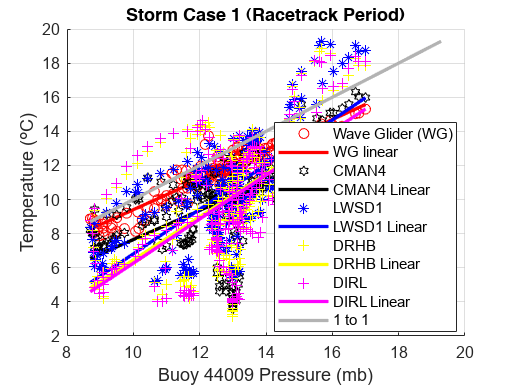

% SCATTER PLOT, DIFFERENCE PLOT and Time Series Plot (Wave Glider and Buoy
% 44009)
%REAL DATA WITHOUT DEPLOYMENT AND RECOVERRY PERIODS)

% Creating a Buoy 44009 and Wave GliderDifferences 
DTemp = BuoyTemp - wgTemp;
Dpres = Buoypres - wgpres;
Dwspd = Buoywspd - wgwspd;
PressDiff = ten_to_30mins(Buoypres) - ten_to_30mins(wgpres);
tempDiff = ten_to_30mins(BuoyTemp) - six_to_30mins(CapeMayTemp);

%Variables for scatter plot (Uncomment variable of interest)
W = wgTemp;
B = BuoyTemp;
C = CapeMayTemp;
L = LewesTemp;
D = DeosRTemp;
I = DeosITemp;

% W = wgpres;
% B = Buoypres;
% C = CapeMaypres;
% L = Lewespres;
% D = DeosRPress;
% I = DeosIPress;
% 
% W = wgwspd;
% B = Buoywspd;
% C = CapeMaywspd;
% L = Leweswspd;
% D = DeosRwspd;
% I = DeosIwspd;

% W = wgwdir;
% B = Buoydir;
% C = CapeMaydir;
% L = Lewesdir;
% D = DeosRwdir;
% I = DeosIwdir;

% Convert all data to 30mins data
W_30mins = ten_to_30mins(W);
B_30mins = ten_to_30mins(B);
D_30mins = five_to_30mins(D);
L_30mins = six_to_30mins(L);
C_30mins = six_to_30mins(C);
I_30mins = five_to_30mins(I);

% Creating a dataframe to filter by windspeed
wgwspd1 = ten_to_30mins(wgwspd);
BuoyTemp1 = ten_to_30mins(Buoywspd);

% Declare the range of interest
%PERIODS
%  1:361:584; waveheight
% 25:385:625; TP&Wind
range = 385:625;

Variable = "Air Temperature ";
Period = "(Station Keeping)";
unit = " (mbar) ";
%  (\circC) 


% Uncomment to filter pressure data when the wave height is above 1m. make sure to run the wave height script first
% % Change for windspeed filter
% mmb=find(WavesHeight(rangeV,:) < 1);


% % Uncomment to filter pressure difference above 1 mbar (you can change the value)
% mmb=find(PressDiff(range,:) > 1 | PressDiff(range,:) < -1 );

% CREATING A DATAFRAME FOR SCENERIO 2
WL11 = (W_30mins(range,:)); 
BL11 = (B_30mins(range,:)); 
DL11 = (D_30mins(range,:)); 
LL11 = (L_30mins(range,:));
CL11 = (C_30mins(range,:));
DI11 = (I_30mins(range,:));

% removing NaN 
WL = (W_30mins(range,:)); WL(isnan(WL)) = [mean(smooth(WL))];
BL = (B_30mins(range,:)); BL(isnan(BL)) = [mean(smooth(BL))];
DL = (D_30mins(range,:)); DL(isnan(DL)) = [mean(smooth(DL))];
LL = (L_30mins(range,:)); LL(isnan(LL)) = [mean(smooth(LL))];
CL = (C_30mins(range,:)); CL(isnan(CL)) = [mean(smooth(CL))];
DI = (I_30mins(range,:)); DI(isnan(DI)) = [mean(smooth(DI))];

% removing NaN
WL12 = WL11; WL12(isnan(WL12)) = [mean(smooth(WL12))];
BL12 = BL11; BL12(isnan(BL12)) = [mean(smooth(BL12))];
DL12 = DL11; DL12(isnan(DL12)) = [mean(smooth(DL12))];
LL12 = LL11; LL12(isnan(LL12)) = [mean(smooth(LL12))];
CL12 = CL11; CL12(isnan(CL12)) = [mean(smooth(CL12))];
DI12 = DI11; DI12(isnan(DI12)) = [mean(smooth(DI12))];


% Datetime in 30mins to be used for plots
Datetime_30 = Dateti(1:3:length(Dateti));
Datte = Datetime_30(range,:);

% Filtering based on Buoy 44004 windspeed/wave height scenerios
% WL(mmb)=NaN;
% BL(mmb)=NaN;
% DL(mmb)=NaN;
% LL(mmb)=NaN;
% CL(mmb)=NaN;
% Datte(mmb) = NaT;
% % DI(mmb)=NaN;

% % removing NaN and replacing with empty cell
% WL(isnan(WL)) = [];
% BL(isnan(BL)) = [];
% DL(isnan(DL)) = [];
% LL(isnan(LL)) = [];
% CL(isnan(CL)) = [];
% DI(isnan(DI)) = [];
% Datte(isnat(Datte)) = [];




% Setting 1 to 1

% to1 = linspace(max(max([W_30mins,B_30mins, D_30mins, L_30mins, C_30mins])), 0, 704);
to1 = linspace(max(max([WL,BL, DL, LL, CL])), min(BL), length (BL));

% Calculating linear trends
linear1 = lineartrend(BL, WL);
linear2 = lineartrend(BL, CL);
linear3 = lineartrend(BL, LL);
linear4 = lineartrend(BL, DL);
linear5 = lineartrend(BL, DI);

linear6 = lineartrend(BL, WL);
linear7 = lineartrend(BL, CL);
linear8 = lineartrend(BL, LL);
linear9 = lineartrend(BL, DL);
linear10 = lineartrend(BL, DI);


figure

%BUOY AND WG
scatter((BL), (WL),'r')
hold on
% Plotting linear trends
plot(linear6(:,1:2),linear6(:,3:4),'r',linewidth = 2)
hold on

%BUOY AND CMAN4
scatter(BL, CL, 'hexagram','k')
hold on
% Plotting linear trends
plot(linear7(:,1:2),linear7(:,3:4),'k',linewidth = 2)
hold on

%BUOY AND LWSD1
scatter(BL, LL,'*','b')
hold on
% Plotting linear trends
plot(linear8(:,1:2),linear8(:,3:4), 'b',linewidth = 2)
hold on

%DEOS RH
scatter(BL, DL,'+','yellow')
hold on

% Plotting linear trends
plot(linear9(:,1:2),linear9(:,3:4),'yellow',linewidth = 2)

hold on

% DEOS IR
scatter(BL, DI,'+','magenta')
hold on

% Plotting linear trends
plot(linear10(:,1:2),linear10(:,3:4),'magenta',linewidth = 2)

hold on
grayColor = [.7 .7 .7];
plot(to1, to1, 'Color', grayColor,linewidth = 2)
hold off
grid on
% grid minor
legend('Wave Glider (WG)','WG linear', 'CMAN4','CMAN4 Linear', 'LWSD1', 'LWSD1 Linear', 'DRHB', 'DRHB Linear','DIRL', 'DIRL Linear','1 to 1',location='best')
% ylim([mean(min([BL,WL,CL,LL,DL,DI])),max(max([BL,WL,CL,LL,DL]))] );
% xlim([mean(min([BL,WL,CL,LL,DL,DI])),max(max([BL,WL,CL,LL,DL]))] ); , 'DIRL', 'DIRL Linear'
ylabel('Temperature (\circC)');
xlabel('Buoy 44009 Pressure (mb)');
title('Storm Case 1 (Racetrack Period)')
% legend('Pressure','1 to 1')
saveas(gcf, append(Variable,' ', 'Scatter plot',Period,'.png'));

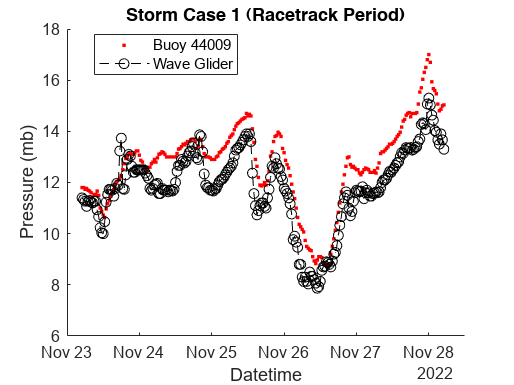



% Time Series plot
figure
hold on
plot(Datte,BL,'.',LineWidth=6, Color='red')
hold on
plot(Datte,WL,'--o',Color='k')
hold off
ylabel('Pressure (mb)');
xlabel('Datetime');
title('Storm Case 1 (Racetrack Period)')
legend('Buoy 44009','Wave Glider',location='best')
saveas(gcf, append(Variable,' ', 'WG and B44009 time series',Period,'.png'));

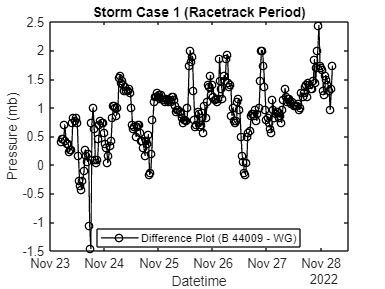



% Difference Plot
plot(Datte,(BL-WL),'-o',LineWidth=1, Color='k')

ylabel('Pressure (mb)');
xlabel('Datetime');
title('Storm Case 1 (Racetrack Period)')
legend('Difference Plot (B 44009 - WG)',location='best')
saveas(gcf, append(Variable,' ', ' WG and B44009 difference plot',Period,'.png'));

% R Squared

Buoy__44009 =BL;
Wave__Glider = WL;
CMAN4 = CL;
LWSD1 = LL;
DRHB = DL;
DIRL = DI;
% Combine data into a table
data = table(Datte, Buoy__44009, Wave__Glider, CMAN4, LWSD1, DRHB, DIRL);
% , DIRL

% List of stations
stations = {'Buoy__44009', 'Wave__Glider', 'CMAN4', 'LWSD1', 'DRHB','DIRL'};
numStations = length(stations);
R_squared_matrix = NaN(numStations, numStations);

% Calculate R-squared for each pair of stations
for i = 1:numStations
    for j = 1:numStations
        if i ~= j
            X = data.(stations{i});
            y = data.(stations{j});
            X = [ones(length(X), 1) X]; % Add a constant term for the intercept
            b = X \ y; % Linear regression coefficients
            y_fit = X * b; % Fitted values
            SS_tot = sum((y - mean(y)).^2); % Total sum of squares
            SS_res = sum((y - y_fit).^2); % Residual sum of squares
            R_squared = 1 - (SS_res / SS_tot); % R-squared value
            R_squared_matrix(i, j) = R_squared;
        end
    end
end

% Display R-squared matrix
disp(append(Variable,' R-squared values between stations ',Period));

Wind Speed  R-squared values between stations (Station Keeping)


disp(array2table(round(R_squared_matrix, 2), 'VariableNames', stations, 'RowNames', stations));

                    Buoy__44009    Wave__Glider    CMAN4    LWSD1    DRHB    DIRL
                    ___________    ____________    _____    _____    ____    ____

    Buoy__44009         NaN            0.82        0.53     0.51     0.23    0.41
    Wave__Glider       0.82             NaN        0.43     0.48      0.2    0.39
    CMAN4              0.53            0.43         NaN     0.57     0.23    0.48
    LWSD1              0.51            0.48        0.57      NaN     0.32    0.36
    DRHB               0.23             0.2        0.23     0.32      NaN    0.31
    DIRL               0.41            0.39        0.48     0.36     0.31     NaN



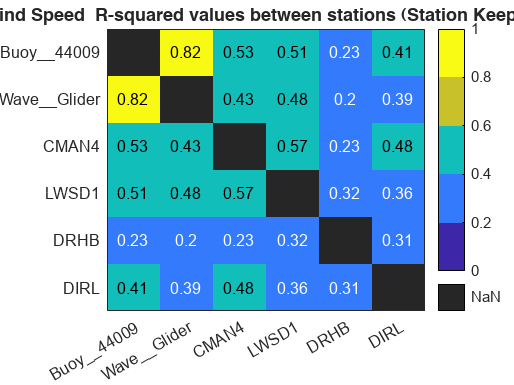



% Visualize the standard deviation matrix using a heatmap
h = heatmap(stations, stations, round(R_squared_matrix, 2), 'Colormap', parula, 'ColorbarVisible', 'on');
h.Title = (append(Variable,' R-squared values between stations ', Period'));
h.ColorLimits = [0 2]; % Adjust limits based on expected range of std deviation differences
h.ColorbarVisible = 'on';
h.GridVisible = 'off';

% Set color intervals of 0.2
caxis([0 1]); % Adjust limits based on expected range of std deviation differences
colormap(parula(5)); % 0 to 2 with intervals of 0.2 means 10 intervals


% Save the heatmap plot as a PNG file
saveas(gcf, append(Variable,' ', ' R-squared values',Period,'.png'));


% Save the standard deviation matrix as a CSV file
std_dev_table = array2table(R_squared_matrix, 'VariableNames', stations, 'RowNames', stations);
writetable(std_dev_table, append(Variable,' ', ' R-squared values ', Period,'.csv'), 'WriteRowNames', true);

% R Squared
Buoy__44009 = BL;
Wave__Glider = WL;
CMAN4 = CL;
LWSD1 = LL;
DRHB = DL;
DIRL = DI;

% Combine data into a table
data = table(Datte, Buoy__44009, Wave__Glider, CMAN4, LWSD1, DRHB, DIRL);

% List of stations
stations = {'Buoy__44009', 'Wave__Glider', 'CMAN4', 'LWSD1', 'DRHB', 'DIRL'};
numStations = length(stations);
R_squared_matrix = NaN(numStations, numStations);
p_value_matrix = NaN(numStations, numStations);

% Calculate R-squared and p-value for each pair of stations
for i = 1:numStations
    for j = 1:numStations
        if i ~= j
            X = data.(stations{i});
            y = data.(stations{j});
            X = [ones(length(X), 1) X]; % Add a constant term for the intercept
            b = X \ y; % Linear regression coefficients
            y_fit = X * b; % Fitted values
            SS_tot = sum((y - mean(y)).^2); % Total sum of squares
            SS_res = sum((y - y_fit).^2); % Residual sum of squares
            R_squared = 1 - (SS_res / SS_tot); % R-squared value
            R_squared_matrix(i, j) = R_squared;
            
            % Compute p-value
            k = 1; % Number of predictors (excluding the constant term)
            n = length(X) - 1; % Number of observations
            F = (R_squared / k) / ((1 - R_squared) / (n - k - 1));
            p_value = 1 - fcdf(F, k, n - k - 1);
            p_value_matrix(i, j) = p_value;
        end
    end
end

% Display R-squared matrix
disp('R-squared values between stations');

R-squared values between stations


disp(array2table(round(R_squared_matrix, 2), 'VariableNames', stations, 'RowNames', stations));

                    Buoy__44009    Wave__Glider    CMAN4    LWSD1    DRHB    DIRL
                    ___________    ____________    _____    _____    ____    ____

    Buoy__44009         NaN            0.82        0.53     0.51     0.23    0.41
    Wave__Glider       0.82             NaN        0.43     0.48      0.2    0.39
    CMAN4              0.53            0.43         NaN     0.57     0.23    0.48
    LWSD1              0.51            0.48        0.57      NaN     0.32    0.36
    DRHB               0.23             0.2        0.23     0.32      NaN    0.31
    DIRL               0.41            0.39        0.48     0.36     0.31     NaN




% Display p-value matrix
disp('P-values between stations');

P-values between stations


disp(array2table(round(p_value_matrix, 4), 'VariableNames', stations, 'RowNames', stations));

                    Buoy__44009    Wave__Glider    CMAN4    LWSD1    DRHB    DIRL
                    ___________    ____________    _____    _____    ____    ____

    Buoy__44009         NaN              0            0        0       0       0 
    Wave__Glider          0            NaN            0        0       0       0 
    CMAN4                 0              0          NaN        0       0       0 
    LWSD1                 0              0            0      NaN       0       0 
    DRHB                  0              0            0        0     NaN       0 
    DIRL                  0              0            0        0       0     NaN 



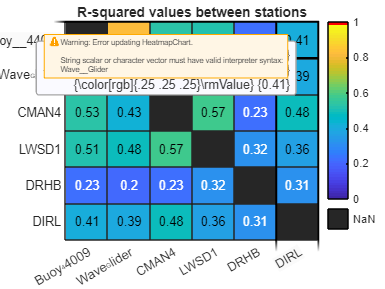


% Define significance threshold (e.g., 0.05 for 95% confidence)
alpha = 0.05;

% Create a heatmap and highlight significant R-squared values
h = heatmap(stations, stations, round(R_squared_matrix, 2), 'Colormap', parula, 'ColorbarVisible', 'on');
h.Title = 'R-squared values between stations';
h.ColorLimits = [0 1];
caxis([0 1]); % Adjust limits based on expected range of R-squared values

% Customize the color map to highlight significant values
highlight = R_squared_matrix .* (p_value_matrix < alpha); % Highlight significant R^2 values
highlight_color = [1 0 0]; % Red color for highlights

% Adjust color map
colormap([parula(64); highlight_color]);

% Save the heatmap plot as a PNG file
saveas(gcf, 'R_squared_values_heatmap.png');


% Save the R-squared matrix and p-value matrix as CSV files
r_squared_table = array2table(R_squared_matrix, 'VariableNames', stations, 'RowNames', stations);
writetable(r_squared_table, 'R_squared_values.csv', 'WriteRowNames', true);

p_value_table = array2table(p_value_matrix, 'VariableNames', stations, 'RowNames', stations);
writetable(p_value_table, 'P_values.csv', 'WriteRowNames', true);


% Prearson correlation

Buoy__44009 = BL;
Wave__Glider = WL;
CMAN4 = CL;
LWSD1 = LL;
DRHB = DL;
DIRL = DI;
% Combine data into a table
data = table(Datte, Buoy__44009, Wave__Glider, CMAN4, LWSD1, DRHB, DIRL);

% List of stations
stations = {'Buoy__44009', 'Wave__Glider', 'CMAN4', 'LWSD1', 'DRHB','DIRL'};
numStations = length(stations);
R_matrix = NaN(numStations, numStations);

% Calculate R for each pair of stations
for i = 1:numStations
    for j = 1:numStations
        if i ~= j
            X = data.(stations{i});
            y = data.(stations{j});
            % Remove NaN values from both X and y
            validIdx = ~isnan(X) & ~isnan(y);
            X = X(validIdx);
            y = y(validIdx);
            if ~isempty(X) && ~isempty(y)
                correlation_matrix = corrcoef(X, y); % Correlation matrix
                R = correlation_matrix(1, 2); % Correlation coefficient
                R_matrix(i, j) = R;
            end
        end
    end
end

% Display R matrix
disp(append(Variable,' R values between stations ',Period));

Atmospheric Pressure  R values between stations (Station Keeping)


disp(array2table(round(R_matrix, 2), 'VariableNames', stations, 'RowNames', stations));

                    Buoy__44009    Wave__Glider    CMAN4    LWSD1    DRHB    DIRL
                    ___________    ____________    _____    _____    ____    ____

    Buoy__44009         NaN            0.93        0.93     0.94     0.94    NaN 
    Wave__Glider       0.93             NaN           1        1        1    NaN 
    CMAN4              0.93               1         NaN     0.99     0.96    NaN 
    LWSD1              0.94               1        0.99      NaN     0.97    NaN 
    DRHB               0.94               1        0.96     0.97      NaN    NaN 
    DIRL                NaN             NaN         NaN      NaN      NaN    NaN 



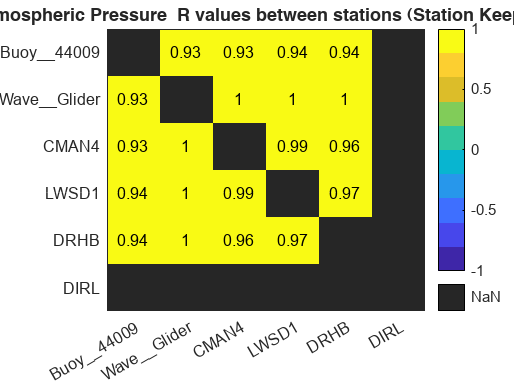


% Visualize the correlation matrix using a heatmap
h = heatmap(stations, stations, round(R_matrix, 2), 'Colormap', parula, 'ColorbarVisible', 'on');
h.Title = (append(Variable,' R values between stations ', Period'));
h.ColorLimits = [-1 1]; % Adjust limits based on expected range of correlation values
h.ColorbarVisible = 'on';
h.GridVisible = 'off';

% Set color intervals of 0.2
caxis([-1 1]); % Adjust limits based on expected range of correlation values
colormap(parula(10)); % -1 to 1 with intervals of 0.2 means 10 intervals

% Save the heatmap plot as a PNG file
saveas(gcf, append(Variable,' ', ' R values',Period,'.png'));


% Save the correlation matrix as a CSV file
correlation_table = array2table(R_matrix, 'VariableNames', stations, 'RowNames', stations);
writetable(correlation_table, append(Variable,' ', ' R values ', Period,'.csv'), 'WriteRowNames', true);


% StDev


Buoy__44009 =BL;
Wave__Glider = WL;
CMAN4 = CL;
LWSD1 = LL;
DRHB = DL;
DIRL = DI;
% Combine data into a table
data = table(Datte, Buoy__44009, Wave__Glider, CMAN4, LWSD1, DRHB, DIRL);

% List of stations
stations = {'Buoy__44009', 'Wave__Glider', 'CMAN4', 'LWSD1', 'DRHB','DIRL'};
numStations = length(stations);
std_dev_matrix = NaN(numStations, numStations);

% Calculate standard deviation for each station
for i = 1:numStations
    for j = 1:numStations
        % Calculate standard deviation for each station
        std_dev_i = std(data.(stations{i}));
        std_dev_j = std(data.(stations{j}));
        
        % Store standard deviation in matrix
        std_dev_matrix(i, j) = abs(std_dev_i - std_dev_j); % Absolute difference for comparison
    end
end

% Display standard deviation matrix
disp(append(Variable,' standard deviation values between stations ', Period));
disp(array2table(round(std_dev_matrix, 2), 'VariableNames', stations, 'RowNames', stations));


% Visualize the standard deviation matrix using a heatmap
% Visualize the standard deviation matrix using a heatmap
h = heatmap(stations, stations, round(std_dev_matrix, 2), 'Colormap', parula, 'ColorbarVisible', 'on');
h.Title = (append(Variable,' standard deviation values between stations ', Period));
h.ColorLimits = [0 2]; % Adjust limits based on expected range of std deviation differences
h.ColorbarVisible = 'on';
h.GridVisible = 'off';


% Save the heatmap plot as a PNG file
saveas(gcf, append(Variable, 'std_dev_heatmap',Period,'.png'));

% Save the standard deviation matrix as a CSV file
std_dev_table = array2table(std_dev_matrix, 'VariableNames', stations, 'RowNames', stations);
writetable(std_dev_table, append(Variable, 'std_dev_matrix',Period,'.csv'), 'WriteRowNames', true);


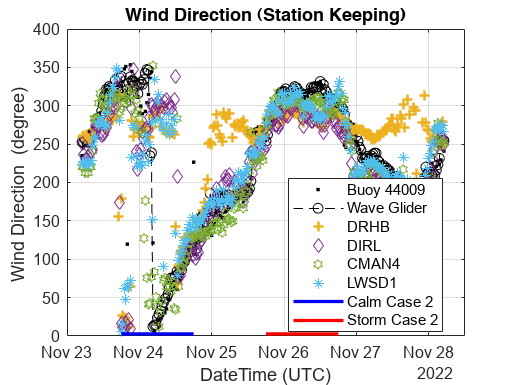

% TIME SERIES PLOT 


% %UNCOMMENT HERE FOR STATION KEEPING
% % % % % % % Station Keeping
xx = datetime('11/23/2022 18:00'); %Start of Calm case 2
yy = datetime('11/24/2022 18:00'); %End of calm case 2
ww = datetime('11/25/2022 18:00'); %Start of Storm Case 2
zz = datetime('11/26/2022 18:00'); %End of Storm case 2
% xline(xx,'--',{'Start Calm case 2'},'LineWidth', 1.5, 'LabelOrientation', 'aligned', 'LabelVerticalAlignment', 'bottom');
% xline(yy,'--',{'End Calm 2, start Storm 2'},'LineWidth',1.5, 'LabelOrientation', 'aligned', 'LabelVerticalAlignment', 'bottom');
% % xline(ww,'--',{'End'},LineWidth=1.5);
% xline(zz,'--',{'End Storm case 2'},'LineWidth',1.5, 'LabelOrientation', 'aligned', 'LabelVerticalAlignment', 'bottom');
% % yline(11,'--',{'Beaufort 6'},Linewidth=1.5, Color= 'red');


% % RACETRACK
% xx = datetime('11/15/2022 12:00'); %Start of Calm case 1
% yy = datetime('11/16/2022 12:00'); %End of calm case 1
% ww = datetime('11/20/2022 06:00'); %Start of Storm Case 1
% zz = datetime('11/21/2022 06:00'); %End of Storm case 1
% xline(xx,'--',{'Start Calm case 1'},'LineWidth', 1.5, 'LabelOrientation', 'aligned', 'LabelVerticalAlignment', 'bottom');
% xline(yy,'--',{'End Calm case 1'},'LineWidth',1.5, 'LabelOrientation', 'aligned', 'LabelVerticalAlignment', 'bottom');
% xline(ww,'--',{'Start storm case 1'},'LineWidth',1.5, 'LabelOrientation', 'aligned', 'LabelVerticalAlignment', 'bottom');
% xline(zz,'--',{'End Storm case 1'},'LineWidth',1.5, 'LabelOrientation', 'aligned', 'LabelVerticalAlignment', 'bottom');
% Define the y-value for the horizontal line and the time range
y_value = min(BL);   % The y-value where the horizontal line will be placed
t_start = xx;     % Start time of the range
t_end = yy;       % End time of the range

% Find the indices corresponding to the specified time range
start_idx = find(Datetime_30(range,:) >= t_start, 1, 'first');
end_idx = find(Datetime_30(range,:) <= t_end, 1, 'last');

D = Datetime_30(range,:);
% Extract the time and value data within the specified range
t_range = D(start_idx:end_idx);
y_line = y_value * ones(size(t_range));

% ****************************************
y_value1 = min(BL);   % The y-value where the horizontal line will be placed
t_start1 = ww;     % Start time of the range
t_end1 = zz;       % End time of the range

% Find the indices corresponding to the specified time range
start_idx1 = find(Datetime_30(range,:) >= t_start1, 1, 'first');
end_idx1 = find(Datetime_30(range,:) <= t_end1, 1, 'last');

D = Datetime_30(range,:);
% Extract the time and value data within the specified range
t_range1 = D(start_idx1:end_idx1);
y_line1 = y_value1 * ones(size(t_range1));

% WL = filloutliers(WL, NaN, 'mean');
% BL = filloutliers(BL, NaN, 'mean');
% CL = filloutliers(CL, NaN, 'mean');
% LL = filloutliers(LL, NaN, 'mean');
% DL = filloutliers(DL, NaN, 'mean');
% DI = filloutliers(DI, NaN, 'mean');

figure
plot(Datte,(BL),'.',LineWidth=6, color = 'k');
hold on
plot(Datte,(WL),'--o',Color='k');
hold on
plot(Datte,(DL),'+', linewidth = 1.5, Color='#EDB120');
hold on
plot(Datte,(DI),'diamond');
hold on
plot(Datte,(CL),'hexagram', Color='#77AC30');
hold on
plot(Datte,(LL),'*', Color='#4DBEEE');
hold on
% plot(Datetim, data_grid(range, :),'square',LineWidth=1.2);
% hold on
% Add the horizontal line within the specified time range
plot(t_range, y_line, 'b-', 'LineWidth', 2);
hold on
plot(t_range1, y_line1, 'r-', 'LineWidth', 2);
hold off

% xticks([Datetim(1:24:312)])
% xtickformat('MMM dd')
% ax = gca;
% ax.XAxis.MinorTick = 'on';
% ax.XAxis.MinorTickValues = Datetim;
grid on;
% ax.XMinorGrid = 'on';

% Nov 20, 06:00 UTC - Nov 21 06:00 UTC STORM CASE 1
% Nov 15, 12:00 UTC - Nov 16 08:00 UTC CALM CASE 1
% Nov 23, 23:00 UTC - Nov 25 15:00 UTC CALM CASE 2
% Nov 25, 05:00 UTC - Nov 26, 05:00 UTC STORM 2


% %UNCOMMENT HERE FOR STATION KEEPING
% % % % % % % Station Keeping
% xx = datetime('11/24/2022 05:00'); %Start of Calm case 2
% yy = datetime('11/25/2022 05:00'); %End of calm case 2
% % ww = datetime('11/25/2022 05:00'); %Start of Storm Case 2
% zz = datetime('11/26/2022 05:00'); %End of Storm case 2
% xline(xx,'--',{'Start Calm case 2'},'LineWidth', 1.5, 'LabelOrientation', 'aligned', 'LabelVerticalAlignment', 'bottom');
% xline(yy,'--',{'End Calm 2, start Storm 2'},'LineWidth',1.5, 'LabelOrientation', 'aligned', 'LabelVerticalAlignment', 'bottom');
% % xline(ww,'--',{'End'},LineWidth=1.5);
% xline(zz,'--',{'End Storm case 2'},'LineWidth',1.5, 'LabelOrientation', 'aligned', 'LabelVerticalAlignment', 'bottom');
% yline(11,'--',{'Beaufort 6'},Linewidth=1.5, Color= 'red');

% CHANGE TITLE AND LEBEL WHEN DATA CHANGES
title(append(Variable, Period))
xlabel('DateTime (UTC)');
% ylabel('Temperature (\circC)');
% ylabel('Wind Speed (m/s)');
ylabel(append(Variable, unit));
legend('Buoy 44009', 'Wave Glider','DRHB','DIRL','CMAN4', 'LWSD1','Calm Case 2', 'Storm Case 2',location='best')
saveas(gcf, append(Variable,Period,'.jpg'));

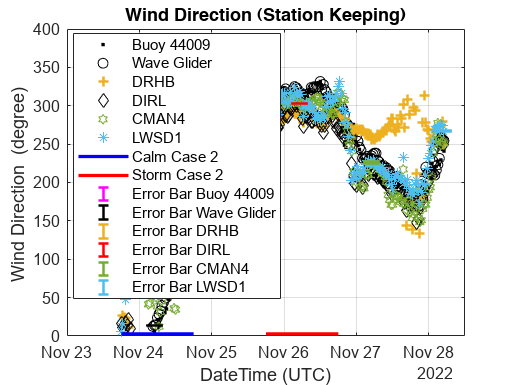

% Define the y-value for the horizontal line and the time range
y_value = min(BL);   % The y-value where the horizontal line will be placed
t_start = xx;        % Start time of the range
t_end = yy;          % End time of the range

% Find the indices corresponding to the specified time range
start_idx = find(Datetime_30(range,:) >= t_start, 1, 'first');
end_idx = find(Datetime_30(range,:) <= t_end, 1, 'last');

D = Datetime_30(range,:);
% Extract the time and value data within the specified time range
t_range = D(start_idx:end_idx);
y_line = y_value * ones(size(t_range));

% ****************************************
y_value1 = min(BL);  % The y-value where the horizontal line will be placed
t_start1 = ww;       % Start time of the range
t_end1 = zz;         % End time of the range

% Find the indices corresponding to the specified time range
start_idx1 = find(Datetime_30(range,:) >= t_start1, 1, 'first');
end_idx1 = find(Datetime_30(range,:) <= t_end1, 1, 'last');

D = Datetime_30(range,:);
% Extract the time and value data within the specified time range
t_range1 = D(start_idx1:end_idx1);
y_line1 = y_value1 * ones(size(t_range1));

figure
% Plot the time series data
plot(Datte, BL, '.', 'LineWidth', 1.5, 'Color', 'k');
hold on
plot(Datte, WL, 'o', 'Color', 'k');
hold on
plot(Datte, DL, '+', 'LineWidth', 1.5, 'Color', [237/255, 177/255, 32/255]);
hold on
plot(Datte, DI, 'd', 'Color', 'k');
hold on
plot(Datte, CL, 'h', 'Color', [119/255, 172/255, 48/255]);
hold on
plot(Datte, LL, '*', 'Color', [77/255, 190/255, 238/255]);
hold on
% Add the horizontal lines within the specified time ranges
plot(t_range, y_line, 'b-', 'LineWidth', 2);
hold on
plot(t_range1, y_line1, 'r-', 'LineWidth', 2);
hold on

% Define error values for each station
err_BL = 1;
err_WL = 0.1;
err_DL = 0;
err_DI = 0;
err_CL = 1;
err_LL = 1;

% Define specific indices for each error bar location to avoid overlap
num_points = length(Datte);
error_indices = round(linspace(1, num_points, 6)); % Example: 6 evenly spaced points

% Plot error bars with matching colors, without white outline
errorbar(Datte(error_indices(1)), BL(error_indices(1)), err_BL, 'm', 'LineStyle', 'none', 'CapSize', 10, 'LineWidth', 1.5); % Error bar (pink)

errorbar(Datte(error_indices(2)), WL(error_indices(2)), err_WL, 'k', 'LineStyle', 'none', 'CapSize', 10, 'LineWidth', 1.5); % Error bar (black)

errorbar(Datte(error_indices(3)), DL(error_indices(3)), err_DL, 'Color', [237/255, 177/255, 32/255], 'LineStyle', 'none', 'CapSize', 10, 'LineWidth', 1.5); % Error bar (orange)

errorbar(Datte(error_indices(4)), DI(error_indices(4)), err_DI, 'r', 'LineStyle', 'none', 'CapSize', 10, 'LineWidth', 1.5); % Error bar (red)

errorbar(Datte(error_indices(5)), CL(error_indices(5)), err_CL, 'Color', [119/255, 172/255, 48/255], 'LineStyle', 'none', 'CapSize', 10, 'LineWidth', 1.5); % Error bar (green)

errorbar(Datte(error_indices(6)), LL(error_indices(6)), err_LL, 'Color', [77/255, 190/255, 238/255], 'LineStyle', 'none', 'CapSize', 10, 'LineWidth', 1.5); % Error bar (blue)

hold off

% Configure plot settings
grid on;
% yline(11, '--', {'Beaufort 6'}, 'LineWidth', 1.5, 'Color', 'red');

% Change title and label when data changes
title(append(Variable, Period))
xlabel('DateTime (UTC)');
ylabel(append(Variable, unit));

% Add legends for data points and error bars, ensuring correct order
legend({'Buoy 44009', 'Wave Glider', 'DRHB', 'DIRL', 'CMAN4', 'LWSD1', ...
    'Calm Case 2', 'Storm Case 2', ...
    'Error Bar Buoy 44009', 'Error Bar Wave Glider', 'Error Bar DRHB', 'Error Bar DIRL', 'Error Bar CMAN4', 'Error Bar LWSD1'}, ...
    'Location', 'best')

% Save the figure
saveas(gcf, append(Variable, Period, '.jpg'));


% STATISTICAL SUMMARY

Buoy__44009 =BL;

Unrecognized function or variable 'BL'.

Wave__Glider = WL;
CMAN4 = CL;
LWSD1 = LL;
DRHB = DL;
DIRL = DI;
% Combine data into a table
data = table(Datte, Buoy__44009, Wave__Glider, CMAN4, LWSD1, DRHB);

% List of stations
stations = {'Buoy__44009', 'Wave__Glider', 'CMAN4', 'LWSD1', 'DRHB'};

% Initialize variables to store statistics
min_values = NaN(1, length(stations));
max_values = NaN(1, length(stations));
mean_values = NaN(1, length(stations));
std_dev_values = NaN(1, length(stations));
r_squared_values = NaN(1, length(stations));
time_of_min = NaT(1, length(stations));
time_of_max = NaT(1, length(stations));

% Calculate statistics for each station
for i = 1:length(stations)
    % Extract data for the station
    station_data = data.(stations{i});
    
    % Calculate statistics
    min_values(i) = min(station_data);
    max_values(i) = max(station_data);
    mean_values(i) = mean(station_data);
    std_dev_values(i) = std(station_data);
    
    % Example: Calculate R-squared (you should replace with your actual computation)
    % Example here computes a dummy R-squared for illustration
    X = (1:length(station_data))';
    y = station_data;
    X = [ones(length(X), 1) X]; % Add a constant term for the intercept
    b = X \ y; % Linear regression coefficients
    y_fit = X * b; % Fitted values
    SS_tot = sum((y - mean(y)).^2); % Total sum of squares
    SS_res = sum((y - y_fit).^2); % Residual sum of squares
    r_squared_values(i) = 1 - (SS_res / SS_tot); % R-squared value (dummy example)
    
    % Example: Calculate time of minimum and maximum
    [~, idx_min] = min(station_data);
    [~, idx_max] = max(station_data);
    time_of_min(i) = Datte(idx_min);
    time_of_max(i) = Datte(idx_max);
end

% Create statistics table
statistics_table = table(min_values', max_values', mean_values', std_dev_values', time_of_min', time_of_max', ...
    'VariableNames', {'Minimum', 'Maximum', 'Mean', 'Standard_Deviation', 'Time_of_Minimum', 'Time_of_Maximum'}, ...
    'RowNames', stations);

% Display statistics table
disp(append(Variable, ' statistics for each station ', Period));
disp(statistics_table);

% Save statistics table as CSV file
writetable(statistics_table, (append(Variable,'statistics_table',Period,'.csv')), 'WriteRowNames', true);


% WL = filloutliers(WL, NaN, 'mean');
% BL = filloutliers(BL, NaN, 'mean');
% CL = filloutliers(CL, NaN, 'mean');
% LL = filloutliers(LL, NaN, 'mean');
% DL = filloutliers(DL, NaN, 'mean');
% DI = filloutliers(DI, NaN, 'mean');
WLBOX = WL;
WLBOX(isnan(WLBOX)) = [];
meann = mean([BL,CL,LL, DL,DI]);
wlmean = mean(WLBOX);
meanWeight1 = ([wlmean, meann]);

%BOXPLOTS
figure
boxchart([WL,BL,CL,LL, DL,DI],'Notch', 'on')
hold on
plot(meanWeight1,'-o')
hold off
legend(["Data","Mean"])
grid on

ylabel(append(Variable, unit));
xlabel('Station');
title(append(Variable, ' Box plot ',Period))
xticklabels({'Wave Glider','Buoy 44009', 'CMAN4','LWSD1','DRHB','DIRL'})
legend(["Data","Mean"],location='best')
grid on
% hold on
% boxchart(BuoyTemp(73:1849,:))

saveas(gcf, append(Variable, ' Box plot ',Period,'.png'));

% %BOXPLOTS
% figure
% boxchart([W(73:1849,:),B(73:1849,:)])
% grid on
% grid minor
% 
% ylabel('Windspeed (m/s)');
% xlabel('Stations');
% title('windspeed > 11.176 (m/s):Nov 15 - 28')
% xticklabels({'WaveGlider','Buoy44009'})
% % hold on
% % boxchart(BuoyTemp(73:1849,:))

% SUMMARY
Buoy__44009 =BL;
Wave__Glider = WL;
CMAN4 = CL;
LWSD1 = LL;
DRHB = DL;
DIRL = DI;
% Combine data into a table
data = table(Datte, Buoy__44009, Wave__Glider, CMAN4, LWSD1, DRHB);

% List of stations
stations = {'Buoy__44009', 'Wave__Glider', 'CMAN4', 'LWSD1', 'DRHB'};

% Initialize variables to store statistics
min_values = NaN(1, length(stations));
max_values = NaN(1, length(stations));
mean_values = NaN(1, length(stations));
std_dev_values = NaN(1, length(stations));
r_squared_values = NaN(1, length(stations));
rmse_values = NaN(1, length(stations));
mae_values = NaN(1, length(stations));
confidence_intervals = NaN(2, length(stations)); % For lower and upper bounds
time_of_min = NaT(1, length(stations));
time_of_max = NaT(1, length(stations));

% Calculate statistics for each station
for i = 1:length(stations)
    % Extract data for the station
    station_data = data.(stations{i});
    
    % Calculate statistics
    min_values(i) = min(station_data);
    max_values(i) = max(station_data);
    mean_values(i) = mean(station_data);
    std_dev_values(i) = std(station_data);
    
    % Example: Calculate R-squared
    X = (1:length(station_data))';
    y = station_data;
    X = [ones(length(X), 1) X]; % Add a constant term for the intercept
    b = X \ y; % Linear regression coefficients
    y_fit = X * b; % Fitted values
    SS_tot = sum((y - mean(y)).^2); % Total sum of squares
    SS_res = sum((y - y_fit).^2); % Residual sum of squares
    r_squared_values(i) = 1 - (SS_res / SS_tot); % R-squared value
    
    % Calculate RMSE
    rmse_values(i) = sqrt(mean((y - y_fit).^2));
    
    % Calculate Mean Absolute Error (MAE)
    mae_values(i) = mean(abs(y - y_fit));
    
    % Calculate 95% Confidence Interval for the mean
    ci = tinv([0.025 0.975], length(y)-1) * std(y)/sqrt(length(y));
    confidence_intervals(:, i) = mean(y) + ci;
    
    % Calculate time of minimum and maximum
    [~, idx_min] = min(station_data);
    [~, idx_max] = max(station_data);
    time_of_min(i) = Datte(idx_min);
    time_of_max(i) = Datte(idx_max);
end

% Create statistics table
statistics_table = table(min_values', max_values', mean_values', std_dev_values', time_of_min', time_of_max', ...
    r_squared_values', rmse_values', mae_values', confidence_intervals(1,:)', confidence_intervals(2,:)', ...
    'VariableNames', {'Minimum', 'Maximum', 'Mean', 'Standard_Deviation', 'Time_of_Minimum', 'Time_of_Maximum', ...
                      'R_Squared', 'RMSE', 'MAE', 'CI_Lower', 'CI_Upper'}, ...
    'RowNames', stations);

% Display statistics table
disp(append(Variable, ' statistics for each station ', Period));

Air Temperature  statistics for each station (Station Keeping)


                    Minimum    Maximum     Mean     Standard_Deviation      Time_of_Minimum         Time_of_Maximum       R_Squared     RMSE      MAE      CI_Lower    CI_Upper
                    _______    _______    ______    __________________    ____________________    ____________________    _________    ______    ______    ________    ________

    Buoy__44009        8.7         17     12.756          1.6448          26-Nov-2022 14:30:00    28-Nov-2022 00:00:00     0.059297     1.592    1.2004     12.548      12.965 
    Wave__Glider    7.8667       15.3     11.834          1.533

disp(statistics_table);

% Save statistics table as CSV file
writetable(statistics_table, (append(Variable,'statistics_table',Period,'.csv')), 'WriteRowNames', true);
